We approximate the integral of the function $f(x)=e^{\sin 7x}$ over the interval $[0,2]$. 

f = @(x) exp(sin(7*x));
a = 0;  b = 2;

In lieu of the exact value, we will use the built-in `integral` function to find an accurate result.

I = integral(f,a,b,'abstol',1e-14,'reltol',1e-14);
fprintf('Integral = %.15f\n',I)

Integral = 2.663219782761539


Here is the error at $n=40$. 

T = trapezoid(f,a,b,40);
err = I - T

err =    9.1685e-04


In order to check the order of accuracy, we double $n$ a few times and observe how the error decreases.

n = 40*2.^(0:5)';
err = zeros(size(n));
for k = 1:length(n)
    T = trapezoid(f,a,b,n(k));
    err(k) = I - T;
end

table(n,err)

ans = 6×2 table
        n            err    
    __________    __________

    4.0000e+01    9.1685e-04
    8.0000e+01    2.3006e-04
    1.6000e+02    5.7568e-05
    3.2000e+02    1.4395e-05
    6.4000e+02    3.5990e-06
    1.2800e+03    8.9975e-07


Each doubling of $n$ cuts the error by a factor of about 4, which is consistent with second-order convergence. Another check: the slope on a log-log graph should be $-2$.

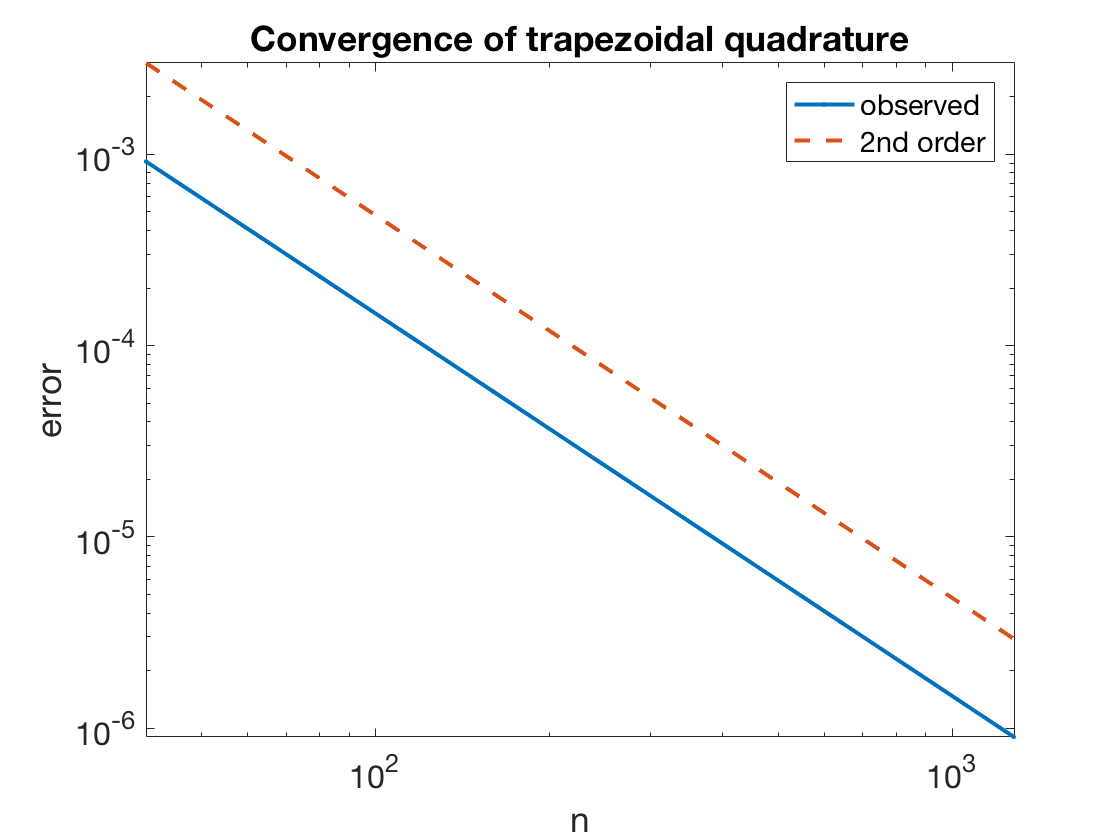

loglog(n,abs(err),'.-')
hold on, loglog(n,3e-3*(n/n(1)).^(-2),'--')
xlabel('n'), ylabel('error'), axis tight        % ignore this line
title('Convergence of trapezoidal quadrature')  % ignore this line
legend('observed','2nd order')               % ignore this line